data=readtable("heart_failure_clinical_records_dataset.csv")

data = 299×13 table
    age    anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ___    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

    75        0                  582                 0               20                     1               2.65e+05          1.9               130  

data_corr1=data(:,{'age','time','serum_creatinine','DEATH_EVENT'})

data_corr1 = 299×4 table
    age    time    serum_creatinine    DEATH_EVENT
    ___    ____    ________________    ___________

    75       4           1.9                1     
    55       6           1.1                1     
    65       7           1.3                1     
    50       7           1.9                1     
    65       8           2.7                1     
    90       8           2.1                1     
    75      10           1.2                1     
    60      10           1.1                1     
    65      10           1.5                1     
    80      10           9.4                1     
    75      10             4                1     
    62      10           0.9                1     
    45      11           1.1                1     
    50      11           1.1                1     
    49      12        

data_corr2=data(:,{'serum_sodium','ejection_fraction','anaemia','DEATH_EVENT'})

data_corr2 = 299×4 table
    serum_sodium    ejection_fraction    anaemia    DEATH_EVENT
    ____________    _________________    _______    ___________

        130                20               0            1     
        136                38               0            1     
        129                20               0            1     
        137                20               1            1     
        116                20               1            1     
        132                40               1            1     
        137                15               1            1     
        131                60               1            1     
        138                65               0            1     
        133                35               1            1     
        131                38               1            1     
      

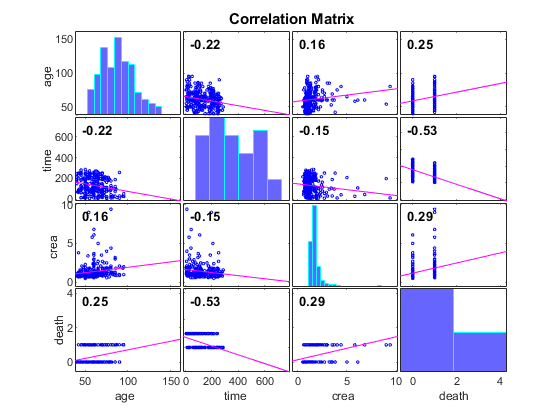

corrplot(data_corr1,'varNames',{'age','time','crea','death'})

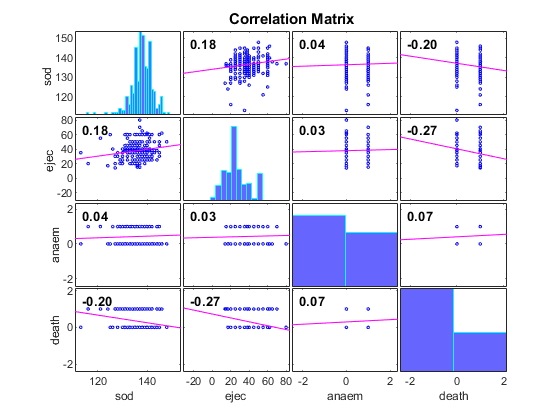

corrplot(data_corr2,'varNames',{'sod','ejec','anaemia','death'})